% Load the data from a file and decode the json into a Matlab struct
fileName = 'data/final_results_202407041000.json';
fid = fopen(fileName);
raw = fread(fid,inf);
str = char(raw');
data = jsondecode(str); % this creates a list of structs describing each jsPsych component in the experiment

% Create a table with only the main experiment sketchpad trials
img_data = {};
for k = 1:size(data, 1)
    temp = struct2table(data{k}, AsArray=true); % read the information about the current jsPsych component into a table format
    if strcmp( temp.trial_type{1}, 'sketchpad' ) && strcmp( temp.task{1}, 'main_experiment' ) % filter out everything besides the main experiment sketchapd trials
        if isempty(img_data) % if this is the first trial, make it the image data table,
            img_data = temp;
        else % otherwise just append the current trial to the image data table
            img_data = [img_data; temp];
        end
    end
end
img_data

img_data = 180×14 table
     rt      response                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                         

% Extract the images from from the data
org_images = img_data.png;
org_images

org_images = 180×1 cell array
    {'data:image/png;base64,iVBORw0KGgoAAAANSUhEUgAABdwAAAK8CAYAAAD1Zn2wAAAgAElEQVR4XuzdS28sV7UH8EqO7XbeKEEwIgoSYsAMMWCCBF8Apsz5XHwChvAFEEwQg0wRQgIimPAKgSQcu+32uVS4hvNwPbp7VfVaVb9Id0K6V639WzuW7t/bu1568u9/Gv8QIECAAAECBAgQIECAAAECBAgQIECAAAECRwm8JHA/ys+XCRAgQIAAAQIECBAgQIAAAQIECBAgQIDAZwICdxuBAAECBAgQIECAAAECBAgQIECAAAECBAgECAjcAxCVIECAAAECBAgQIECAAAECBAgQIECAAAECAnd7gAABAgQIECBAgAABAgQIECBAgAABAgQIBAgI3AMQlSBAgAABAgQIECBAgAABAgQIECBAgAABAgJ3e4AAAQIECBAgQIAAAQIECBAgQIAAAQIECAQICNwDEJUgQIAAAQIECBAgQIAAAQIECBAgQIAAAQICd3uAAAECBAgQIECAAAECBAgQIECAAAECBAgECAjcAxCVIECAAAECBAgQIECAAAECBAgQIECAAAECAnd7gAABAgQIECBAgAABAgQIECBAgAABAgQIBAgI3AMQlSBAgAABAgQIECBAgAABAgQIECBAgAABAgJ3e4AAAQIECBAgQIAAAQIECBAgQIAAAQIECAQICNwDEJUgQIAAAQIECBAgQIAAAQIECBAgQIAAAQICd3uAAAECBAgQIECAAAECBAgQIECAAAECBAgECAjcAxCVIECAAAECBAgQIECAAAECBAgQIECAAAECAnd7gAABAgQIECBAgAABAgQIECBAgAABAgQIBAgI3AMQlSBAgAABAgQIECBAgAABAgQIECBAgAABAgJ3e4AAAQIECBAgQIAAAQIECBAgQIAAAQIECAQICNwDEJUgQIAAAQIECBAgQIAAAQ

len = size(org_images);
len = len(1);

% Extract all the drawing images from the data
images = zeros(len, 700, 1500, 3);
complete = zeros(len, 1);
for i = 1:len
    images(i, :, :, :) = dataURLtoImage(org_images{i}, i);
    complete(i) = checkCompleteness(squeeze(images(i, :, :, :)));
end

% Extract all the stimuli images from the data
stimuli = img_data.stimulus_path;
stim_images = zeros(len, 280, 280);
for i = 1:len
    stim_images(i, :, :) = imread(stimuli{i});
end

nnz(complete) % number of complete drawings

ans = 177

% find the turning distance similarity measure between each stimulus and
% participant's drawing
similarity = zeros(len, 1);
for i = 1:len
    if complete(i)
        drawing = imageToPolygon(squeeze(images(i, :, :, :)), 1, 0);
        stim = imageToPolygon(squeeze(stim_images(i, :, :)), 1, 0);
        similarity(i) = turningdist(drawing, stim);
    end
end

similarity

similarity =     0.6893
    0.8574
    0.8735
    0.7747
    0.7724
    1.0597
    0.7445
    0.7237
    0.7713
    0.7020


% Save the similarities for short and long stimulus durations to separate
% arrays
short = zeros(1, len/2);
short_i = 1;
long = zeros(1, len/2);
long_i = 1;
for i = 1:len
    if similarity(i) ~= 0 % 0 is saved when the drawing is incomplete
        if img_data.stim_dur(i) == 1000
            long(long_i) = similarity(i);
            long_i = long_i + 1;
        else
            short(short_i) = similarity(i);
            short_i = short_i + 1;
        end
    else % when the drawing is incomplete, save a NaN which will be ignored in subsequent statistical analysis
       if img_data.stim_dur(i) == 1000
            long(long_i) = NaN;
            long_i = long_i + 1;
        else
            short(short_i) = NaN;
            short_i = short_i + 1;
       end
    end
end
short

short =     0.7747    0.7724    0.7445    0.7713    0.7370    0.7430    0.7270    0.8177    0.6995    0.6661    0.6950    0.7020    0.7612    0.7995    0.7881    0.7182    0.6601    0.8176    0.7003    0.7162    1.7163    0.6341    0.8225    0.6418    0.6893    0.8333    0.6927    0.8209    0.7130    0.7713    0.9076    0.7827    0.7236    0.8476    0.7170    0.6962    0.6832    0.6470    0.7687    0.6733    0.7078    0.8084    0.6945       NaN    0.6575    0.7462    0.7680    0.7320    0.6544    0.7068


long

long =     0.6893    0.8574    0.8735    1.0597    0.7237    0.7020    0.6699    0.6583    0.6693    0.6792    0.6523    0.7885    0.7789    0.6955    0.6663    0.7291    0.8174    0.8209    0.7301    0.8304    0.7251    0.6695    0.6084    0.6647    0.7671       NaN    0.8376    0.6707    0.7295    0.6783    0.7281    0.7363    0.7413    0.8266    0.8208    0.8892    0.6871    0.6783    0.6913    0.7135    0.8348    0.8501    0.6751    0.7089    0.7969    0.6220    0.7091    0.6537    0.6228    0.7458


nanmean(short)

ans = 0.7501

nanmean(long)

ans = 0.7375

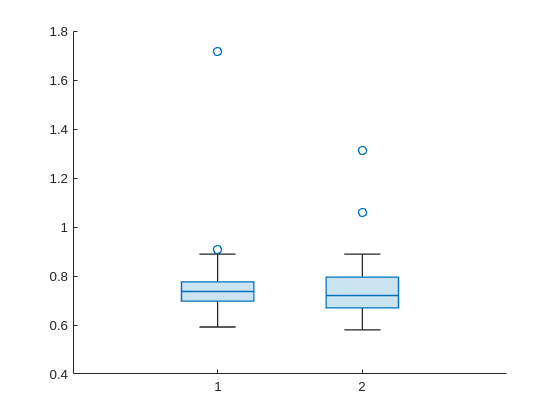

boxchart(transpose([short; long]))

[h,p,ci,stats] = ttest2(short, long)

h = 0

p = 0.4580

ci =    -0.0207    0.0458


stats = struct with fields:
    tstat: 0.7438
       df: 175
       sd: 0.1122


% The code below visualises the steps of transforming an image to a
% polygon (useful for checking anomalies)

% i = 2; 
% 
% img = squeeze(images(i, :, :, :));
% img = im2bw(img);
% imshow(img);
% 
% invImg = imcomplement(img);
% imshow(invImg);
% 
% se90 = strel('line',1,90);
% se0 = strel('line',1,0);
% invImg = imdilate(invImg,[se90 se0]);
% imshow(invImg);
% 
% fillImg = imfill(invImg, "holes");
% imshow(fillImg);
% 
% checkCompleteness(img)
% 
% [B,L] = bwboundaries(fillImg,'noholes');
% imshow(label2rgb(L, @jet, [.5 .5 .5]))
% hold on
% for k = 1:length(B)
%    boundary = B{k};
%    plot(boundary(:,2), boundary(:,1), 'w', 'LineWidth', 2)
% end
% 
% p_reduced = reducepoly(B{1}, 0);
% line(p_reduced(:,2),p_reduced(:,1), ...
%        'color','b','linestyle','-','linewidth',1.5,...
%        'marker','o','markersize',5);
% 
% org_stim = squeeze(stim_images(i, :, :));
% imshow(org_stim)
% 
% bw_stim = im2bw(org_stim, 0.99);
% imshow(bw_stim)
% 
% inv_stim = imcomplement(bw_stim);
% inv_stim = imfill(inv_stim, "holes");
% [Bs,Ls] = bwboundaries(inv_stim,'noholes');
% figure
% imshow(label2rgb(Ls, @jet, [.5 .5 .5]))
% hold on
% for k = 1:length(Bs)
%    boundary = Bs{k};
%    plot(boundary(:,2), boundary(:,1), 'w', 'LineWidth', 2)
% end
% 
% s_reduced = reducepoly(Bs{1}, 0.0);
% line(s_reduced(:,2),s_reduced(:,1), ...
%        'color','b','linestyle','-','linewidth',1.5,...
%        'marker','o','markersize',5);
% 
% n_s = size(s_reduced, 1)-1
% s_vertices = s_reduced(1:n_s,:);
% stim_pol = polyshape(s_vertices);
% stim_pol
% 
% isequal(stim_pol, imageToPolygon(squeeze(stim_images(i, :, :)), 1, 0))
% 
% n = size(p_reduced, 1)-1
% vertices = p_reduced(1:n,:);
% polygon = polyshape(vertices);
% [xc, yc] = centroid(polygon)
% radiuses = zeros(n, 1);
% for i = 1:n
%     radiuses(i) = norm([vertices(i, 1), vertices(i, 2)] - [xc, yc]);
% end
% radiuses
% polygon
% polygon.boundary
% 
% isequal(polygon, imageToPolygon(img, 1, 0))
% 
% turningdist(polygon, stim_pol)